clear;
m = mobiledev('OnePlus 6T')

m = mobiledev with properties:

                      Device: 'OnePlus 6T'
                   Connected: 1
            AvailableCameras: {'back' 'front'}
                     Logging: 0
            InitialTimestamp: ''

   AccelerationSensorEnabled: 1
AngularVelocitySensorEnabled: 1
       MagneticSensorEnabled: 0
    OrientationSensorEnabled: 1
       PositionSensorEnabled: 0

Supported functions

%start logging
m.Logging = 1 

m = mobiledev with properties:

                      Device: 'OnePlus 6T'
                   Connected: 1
            AvailableCameras: {'back' 'front'}
                     Logging: 1
            InitialTimestamp: ''

   AccelerationSensorEnabled: 1
AngularVelocitySensorEnabled: 1
       MagneticSensorEnabled: 0
    OrientationSensorEnabled: 1
       PositionSensorEnabled: 0

Current Sensor Values:
                Acceleration: [0x3 double] (Waiting for data)
             AngularVelocity: [0x3 double] (Waiting for data)
                 Orientation: [0x3 double] (Waiting for data)

Supported functions

%stop logging
m.Logging = 0

m = mobiledev with properties:

                      Device: 'OnePlus 6T'
                   Connected: 1
            AvailableCameras: {'back' 'front'}
                     Logging: 0
            InitialTimestamp: '19-Jul-2021 12:36:39.894'

   AccelerationSensorEnabled: 1    (681 Logged values)
AngularVelocitySensorEnabled: 1    (690 Logged values)
       MagneticSensorEnabled: 0
    OrientationSensorEnabled: 1    (690 Logged values)
       PositionSensorEnabled: 0

Supported functions

%see current value
% disp(m)

%see log of acceleration
[a, t] = accellog(m);
aFilt = move_avg_filt(a, 5);
% figure()
% subplot(3,1,1)
% plot(t, a(:, 1))
% subplot(3,1,2)
% plot(t, a(:, 2))
% subplot(3,1,3)
% plot(t, a(:, 3))
fftAccel = fft_from_time(aFilt, 100);
fftAccelNo0 = remove_0(fftAccel);


% just good in frequency domain
clf
figure()
hold on

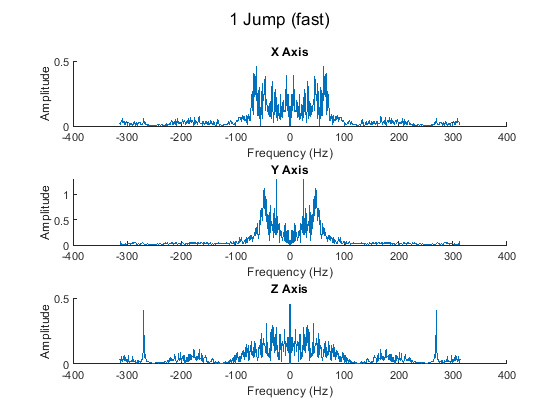

sgtitle('1 Jump (fast)')
subplot(3,1,1)
hold on
plot(fftAccelNo0(:,1), abs(fftAccelNo0(:,2)))
%plot(b1_5(:,1), abs(b1_5(:,2)))

%legend('Good')%, 'Bad')
title('X Axis')
xlabel('Frequency (Hz)')
ylabel('Amplitude')
hold off
subplot(3,1,2)
hold on
plot(fftAccelNo0(:,1), abs(fftAccelNo0(:,3)))
%plot(b1_5(:,1), abs(b1_5(:,3)))
%legend('Good')%, 'Bad')
title('Y Axis')
xlabel('Frequency (Hz)')
ylabel('Amplitude')
hold off
subplot(3,1,3)
hold on
plot(fftAccelNo0(:,1), abs(fftAccelNo0(:,4)))
%plot(b1_5(:,1), abs(b1_5(:,4)))
%legend('Good')%, 'Bad')
title('Z Axis')
xlabel('Frequency (Hz)')
ylabel('Amplitude')
hold off

discardlogs(m)
disp(m)

mobiledev with properties:

                      Device: 'OnePlus 6T'
                   Connected: 1
            AvailableCameras: {'back' 'front'}
                     Logging: 0
            InitialTimestamp: ''

   AccelerationSensorEnabled: 1
AngularVelocitySensorEnabled: 1
       MagneticSensorEnabled: 0
    OrientationSensorEnabled: 1
       PositionSensorEnabled: 0

Supported functions


function data = fft_from_time(time_data, Fs)
%fft_from_time perfoms the fast fourier transform on time_data
%time_data: [3 x N]: col 1: x, col 2: y, col 3: z
%Fs: sampling rate data was collected at

%take shifted fft
fft_x = fftshift(fft(time_data(:,1)));
fft_y = fftshift(fft(time_data(:,2)));
fft_z = fftshift(fft(time_data(:,3)));

%find shifted frequencies
N = length(time_data(:,1));
f_shifted = linspace(-pi * Fs, (pi-2/N*pi) * Fs, N) + Fs * pi/N*mod(N,2);
f_shifted = f_shifted';

%package into data matrix
%column 1: shifted frequencies
%column 2: fft of x direction
%column 3: fft of y direction
%column 4: fft of z direction
data = [f_shifted fft_x fft_y fft_z];
end

function freq_data = remove_0(freq_data)
% remove_0 removes the 0Hz frequency from all axes
% input freq_data: frequency data matrix (N x 3)

    %for each axis: find max frequency (will be 0Hz) and make amplitude 0
    for i=2:4
        [~, Index] = max(freq_data(:,i));
        freq_data(Index, i) = 0;
    end
end